# Análisis de composición de Nodos Escenario 4

% Bikenode -> 1
% Bicyclenode -> 2
% Pednode -> 3
% Car -> 4 

ind = zeros(4,10);
for i=1:length(HD_Nodes)
    for k=0:9
        if HD_Nodes(i,1) <= 38500+k && HD_Nodes(i,2)>38500+k
            ind(HD_Nodes(i,3),k+1)=ind(HD_Nodes(i,3),k+1)+1;
        end
    end
end        
    

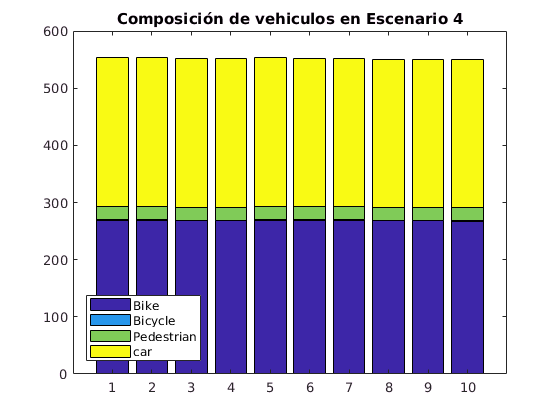

bar(ind','stacked')
title('Composición de vehiculos en Escenario 4')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0,11])


ind

ind =    269   269   268   268   269   269   269   268   268   267
     1     1     1     1     1     1     1     1     1     1
    23    23    23    23    23    23    23    23    23    23
   260   260   260   260   260   259   259   259   259   260



sum(ind)

ans =    553   553   552   552   553   552   552   551   551   551


# Análisis de composición de Nodos Escenario 1

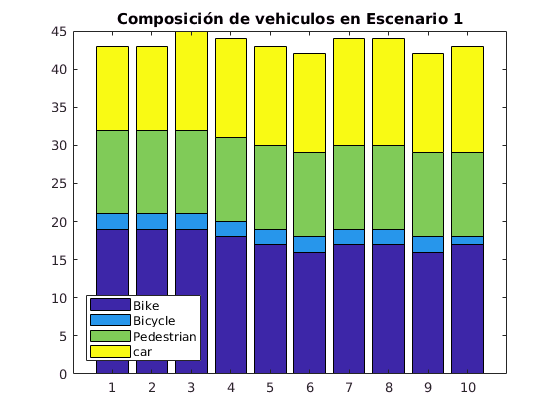

ind2 = zeros(4,10);
for i=1:length(LD_Nodes)
    for k=0:9
        if LD_Nodes(i,1) <= 23500+k && LD_Nodes(i,2)>23500+k
            ind2(LD_Nodes(i,3),k+1)=ind2(LD_Nodes(i,3),k+1)+1;
        end
    end
end 

bar(ind2','stacked')
title('Composición de vehiculos en Escenario 1')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0,11])

ind2

ind2 =     19    19    19    18    17    16    17    17    16    17
     2     2     2     2     2     2     2     2     2     1
    11    11    11    11    11    11    11    11    11    11
    11    11    13    13    13    13    14    14    13    14


sum(ind2)

ans =     43    43    45    44    43    42    44    44    42    43


# Diferencias Escenario sin Obstáculos Escenario 4 - r=10Hz

- Para el escenario con obstaculos se consideran 10 repeticiones mientras en el que no se consideran solo se toma una corrida.

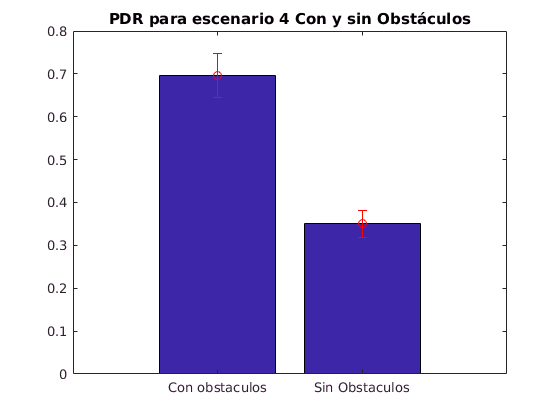

PDR = [0.696 0.350];
PDR_STD = [0.052 0.032];

CBR = [0.2010 0.2839];
CBR_STD = [0.0259 0.00181];

bar(PDR)
hold on
errorbar(PDR,PDR_STD, 'ro')
hold off
xlim([0,3]);
title('PDR para escenario 4 Con y sin Obstáculos');
xticklabels({'Con obstaculos','Sin Obstaculos'});

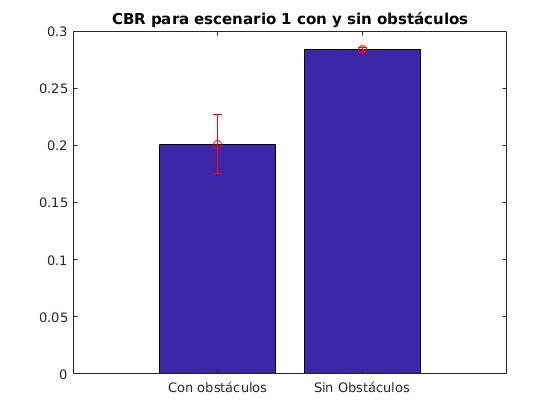

bar(CBR)
hold on
errorbar(CBR,CBR_STD, 'ro')
hold off
xlim([0,3]);
title('CBR para escenario 1 con y sin obstáculos');
xticklabels({'Con obstáculos','Sin Obstáculos'});

# Diferencias Escenario sin Obstáculos Escenario 1 - r=1Hz

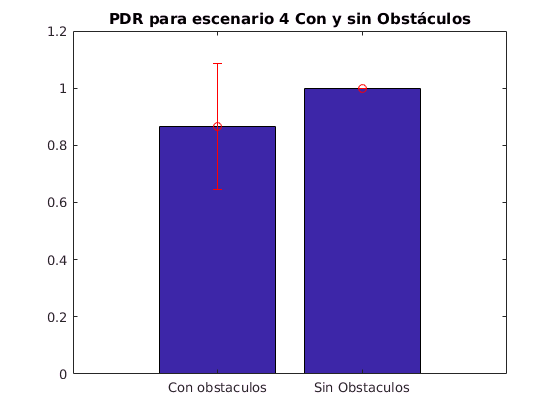

PDR = [0.865 1.0];
PDR_STD = [0.22 0];

CBR = [0.00086 0.0044];
CBR_STD = [0.000316 9.530237957286526e-05];

bar(PDR)
hold on
errorbar(PDR,PDR_STD, 'ro')
hold off
xlim([0,3]);
title('PDR para escenario 4 Con y sin Obstáculos');
xticklabels({'Con obstaculos','Sin Obstaculos'});

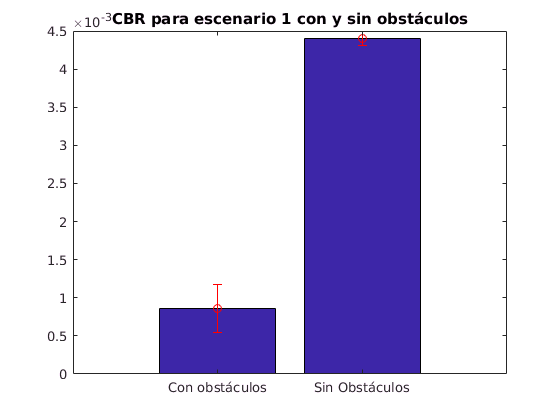

bar(CBR)
hold on
errorbar(CBR,CBR_STD, 'ro')
hold off
xlim([0,3]);
title('CBR para escenario 1 con y sin obstáculos');
xticklabels({'Con obstáculos','Sin Obstáculos'});